## **环境交互测试实验4：人在回路**

%% 添加必要的路径
run('path_add.m')
clear,clc

% 加载数据
filename = "Forest_data.mat";
% 使用exist函数检查文件是否存在  
if exist(filename, 'file') == 2  
    load Forest_environment\Forest_data.mat 
else  
    run("Forest_environment\Forest_generate.m")
    load Forest_environment\Forest_data.mat
end
if exist("Env_test_Data\fieldShape.mat", 'file') == 2  
    load Env_test_Data\fieldShape.mat
else  
    [points,points_field] = fieldShape_generate(trees, field_tree);
    save Env_test_Data\fieldShape.mat points_field points
end

% 加载T2中的数据
load Env_test_Data\T2_data_train.mat

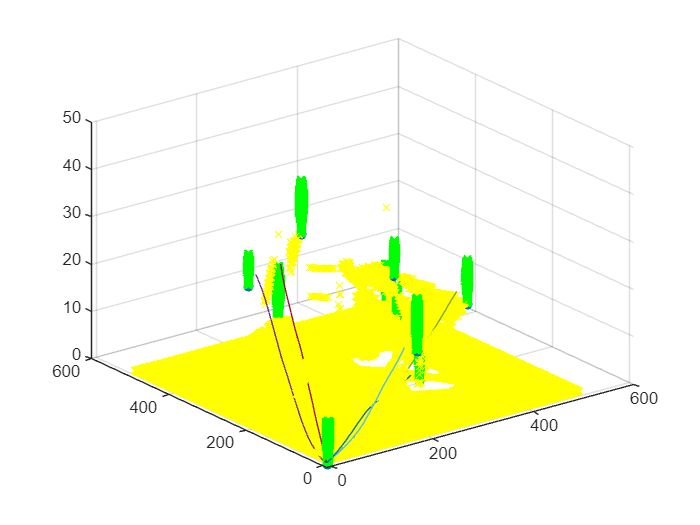

% 让我们将环境和轨迹简单的画出来吧
figure(1)
scatter3(information_tree(:,1),information_tree(:,2),information_tree(:,3),'filled','o')
hold on
scatter3(points(:,1),points(:,2),points(:,3),'green','x')
scatter3(points_field(:,1),points_field(:,2),points_field(:,3),'yellow','x')
for i=1:length(uavs)
    plot3(uavs(i).position(:,1),uavs(i).position(:,2),uavs(i).position(:,3))
end
hold off

% 加载一些无人机
% 得到待侦察目标位置,以树的顶端作为搜索目标
nodes_target = [selectedNumbers_firepoint,selectedNumbers_burn];
points_target = information_tree(nodes_target,1:3);
for i=1:length(nodes_target)
    points_target(i,3) = points_target(i,3)+trees(nodes_target(i)).height;
end
max_speed = 200;
max_range = 60;
max_altitude = 310;
max_power = 5000;
max_load = 25;
k_up = 0.05;
k_down = 0.01;
k_around = 0.03;
dt = 0.1;
uav_0 = uav(max_speed,max_range,max_altitude,max_power,max_load,k_up,k_down,k_around,dt);
uavs = [];
for i=1:size(points_target, 1)
    temp_uav = uav_0.current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1]);
    uavs = [uavs;temp_uav];
end

## 快速强化学习训练过程

numtofly = 20;
ways_before = []; % 存储无人机的位置
ways_after = [];
interval = 3;
sa_collect = cell(length(uavs), 1); % 收集智能体的决策状态
for i=1:length(uavs)
    ways_before = [ways_before;uavs(i).position(1:interval:end,:)];
end
for i=1:length(uavs)
    uavs(i) = uavs(i).current_properties_reset(8/10*max_speed,0,max_power,max_load/2,[-10,-10,1]);
    [uavs(i), agents(i), SA] = fly_ByAgent(uavs(i), agents(i), points_target(i,:), trees, field_tree, 1);
    sa_collect{i} = SA;
end
for i=1:length(uavs)
    ways_after = [ways_after;uavs(i).position(1:interval:end,:)];
end
save Env_test_Data\T4_data_ways ways_before ways_after

% 如果路径好的话，将路径更新到经验池中进行训练
epochs = 50;
batch_size = 40; % 输入最大批量大小
for i=1:length(uavs)
    agents(i) = agents(i).pop_experience(size(sa_collect{i}, 1));
    agents(i) = agents(i).add_experience(sa_collect{i});
    for train_num = 1:epochs
        agents(i) = agents(i).update(batch_size);  % 更新参数
    end
end

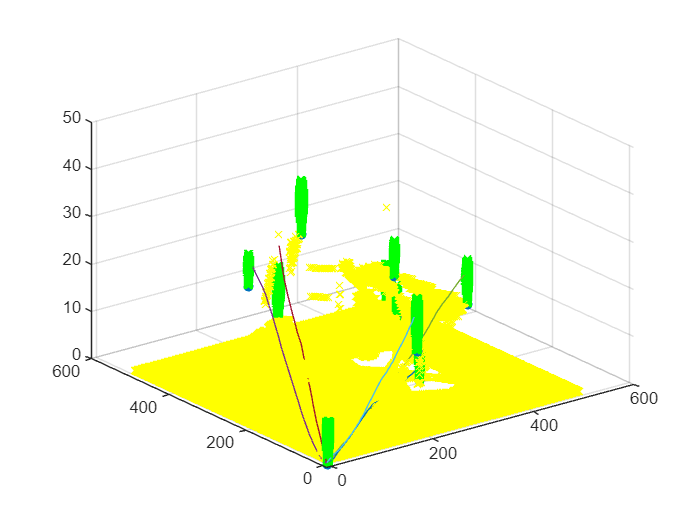

% 让我们将环境和轨迹简单的画出来吧
figure(2)
scatter3(information_tree(:,1),information_tree(:,2),information_tree(:,3),'filled','o')
hold on
scatter3(points(:,1),points(:,2),points(:,3),'green','x')
scatter3(points_field(:,1),points_field(:,2),points_field(:,3),'yellow','x')
for i=1:length(uavs)
    plot3(uavs(i).position(:,1),uavs(i).position(:,2),uavs(i).position(:,3))
end
hold off